[nc, fs] = audioread('audio_experiments/mics_nc.wav');
[foam, fs] = audioread('audio_experiments/mics_foam.wav');

t = (0:length(foam(:, 1)) - 1) / fs;

figure
plot(t, nc(:, 1))
hold on
plot(t, foam(:, 1))
legend('panel reverb', 'foam')
title('No with foam vs panel reverb')
ylabel('Amplitude')
xlabel('Time (s)')
xlim([t(1), t(end)])


target = nc(:, 1) - foam(:, 1);
ref = nc(:, 2);

cutoff = 400;
target_hp = highpass(target, cutoff, fs);
ref_hp = highpass(ref, cutoff, fs);

source_to_ref = 2;
ir_len = 64;
filter_order = 2 * ir_len;
step_size = .0001;

panel_ir = clipped_irs(ir_len, source_to_ref);
panel_ir_hp = highpass(panel_ir, cutoff, fs);

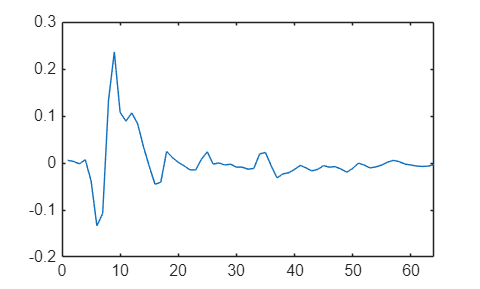

figure
plot(panel_ir_hp)

step_sizes = [.0005, .0001, .00005, .00001, .000005, .000001];
n_iter = 1000;
mses = zeros(length(step_sizes), n_iter);
for i = 1:length(step_sizes)
    fxlms = FxLMS(ref, target, panel_ir, filter_order, step_sizes(i), true);
    [pred_i, mses_i] = fxlms.learn(n_iter);
    mses(i, :) = mses_i;
    mses_i
end

mses_i = 1.0e-05 *

    0.8013    0.6568    0.6161    0.6106    0.6161    0.6242    0.6318    0.6383    0.6436    0.6479    0.6514    0.6542    0.6566    0.6587    0.6605    0.6621    0.6635    0.6649    0.6661    0.6673    0.6684    0.6695    0.6705    0.6714    0.6724    0.6733    0.6741    0.6750    0.6758    0.6765    0.6773    0.6780    0.6787    0.6794    0.6801    0.6807    0.6813    0.6819    0.6825    0.6831    0.6836    0.6842    0.6847    0.6852    0.6857    0.6862    0.6866    0.6871    0.6875    0.6880


mses_i = 1.0e-04 *

    0.1054    0.0954    0.0871    0.0803    0.0747    0.0702    0.0665    0.0636    0.0613    0.0595    0.0581    0.0569    0.0561    0.0555    0.0550    0.0547    0.0545    0.0544    0.0544    0.0544    0.0544    0.0545    0.0546    0.0548    0.0549    0.0551    0.0552    0.0554    0.0555    0.0557    0.0559    0.0560    0.0562    0.0563    0.0565    0.0566    0.0568    0.0569    0.0570    0.0571    0.0573    0.0574    0.0575    0.0576    0.0577    0.0578    0.0579    0.0579    0.0580    0.0581


mses_i = 1.0e-04 *

    0.1106    0.1031    0.0978    0.0930    0.0886    0.0846    0.0809    0.0776    0.0747    0.0720    0.0696    0.0674    0.0655    0.0637    0.0622    0.0608    0.0596    0.0585    0.0575    0.0566    0.0558    0.0552    0.0546    0.0540    0.0536    0.0532    0.0529    0.0526    0.0523    0.0521    0.0519    0.0518    0.0517    0.0516    0.0515    0.0515    0.0514    0.0514    0.0514    0.0514    0.0514    0.0515    0.0515    0.0516    0.0516    0.0517    0.0517    0.0518    0.0519    0.0519


mses_i = 1.0e-04 *

    0.1315    0.1210    0.1154    0.1119    0.1093    0.1074    0.1057    0.1043    0.1030    0.1018    0.1006    0.0995    0.0984    0.0973    0.0963    0.0952    0.0942    0.0932    0.0923    0.0913    0.0904    0.0894    0.0885    0.0876    0.0868    0.0859    0.0851    0.0842    0.0834    0.0826    0.0819    0.0811    0.0804    0.0796    0.0789    0.0782    0.0775    0.0769    0.0762    0.0756    0.0749    0.0743    0.0737    0.0731    0.0725    0.0720    0.0714    0.0709    0.0703    0.0698


mses_i = 1.0e-04 *

    0.1409    0.1312    0.1251    0.1208    0.1177    0.1153    0.1134    0.1119    0.1105    0.1094    0.1083    0.1074    0.1066    0.1058    0.1050    0.1043    0.1037    0.1030    0.1024    0.1018    0.1012    0.1006    0.1000    0.0995    0.0989    0.0984    0.0978    0.0973    0.0968    0.0962    0.0957    0.0952    0.0947    0.0942    0.0937    0.0932    0.0927    0.0922    0.0917    0.0912    0.0908    0.0903    0.0898    0.0893    0.0889    0.0884    0.0880    0.0875    0.0871    0.0867


mses_i = 1.0e-04 *

    0.1531    0.1495    0.1462    0.1433    0.1407    0.1384    0.1363    0.1344    0.1326    0.1310    0.1296    0.1282    0.1270    0.1259    0.1249    0.1239    0.1230    0.1222    0.1214    0.1207    0.1200    0.1194    0.1188    0.1182    0.1177    0.1171    0.1167    0.1162    0.1158    0.1153    0.1149    0.1145    0.1142    0.1138    0.1135    0.1131    0.1128    0.1125    0.1122    0.1119    0.1116    0.1114    0.1111    0.1108    0.1106    0.1104    0.1101    0.1099    0.1097    0.1094


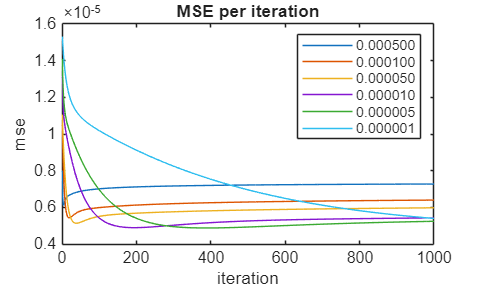

figure
for i = 1:length(step_sizes)
    plot(mses(i, :), 'DisplayName', sprintf('%f', step_sizes(i)))
    hold on
end
hold off
title('MSE per iteration')
xlabel('iteration')
ylabel('mse')
legend()

lr_schedule = @(iter) 1 / (2 * iter^2);
lr_schedule = @(t) max(1e-5, 0.9 * exp(-t / 5));
fxlms = FxLMS(ref, target, panel_ir, filter_order, lr_schedule, true);
[pred, mse] = fxlms.learn(50);
mse

mse = 1.0e-04 *

    0.1625    0.0639    0.0674    0.0740    0.0738    0.0720    0.0694    0.0664    0.0639    0.0622    0.0612    0.0606    0.0602    0.0600    0.0598    0.0597    0.0596    0.0596    0.0596    0.0595    0.0595    0.0595    0.0595    0.0595    0.0595    0.0595    0.0595    0.0595    0.0595    0.0595    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594    0.0594


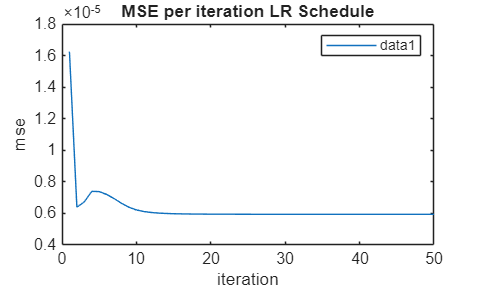

figure
plot(mse)
title('MSE per iteration LR Schedule')
xlabel('iteration')
ylabel('mse')
legend()

lr_schedule = @(t) max(1e-5, 0.9 * exp(-t / 5));
lr_schedule = @(t) max(1e-5, 1 ./ (1 + 0.01 * t));
fxlms = FxLMS(ref, target, panel_ir, filter_order, lr_schedule, true);
[pred, mse] = fxlms.learn(80);
mse

mse = 1.0e-04 *

    0.2343    0.1951    0.1628    0.1358    0.1142    0.0981    0.0868    0.0792    0.0744    0.0715    0.0698    0.0686    0.0678    0.0669    0.0661    0.0654    0.0648    0.0645    0.0645    0.0648    0.0653    0.0659    0.0666    0.0675    0.0686    0.0699    0.0713    0.0727    0.0739    0.0748    0.0754    0.0757    0.0757    0.0755    0.0752    0.0748    0.0743    0.0737    0.0731    0.0724    0.0715    0.0705    0.0695    0.0683    0.0672    0.0661    0.0650    0.0642    0.0634    0.0628


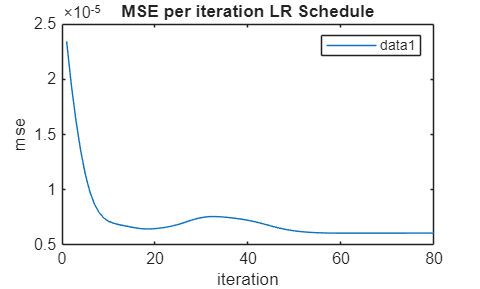

figure
plot(mse)
title('MSE per iteration LR Schedule')
xlabel('iteration')
ylabel('mse')
legend()

lr_schedule = @(t) max(1e-5, 1 / (t + 4));
fxlms = FxLMS(ref_hp, target_hp, panel_ir_hp, filter_order, lr_schedule, true);
[pred, mse] = fxlms.learn(100);
mse

mse = 1.0e-05 *

    0.5376    0.5332    0.5336    0.5354    0.5373    0.5386    0.5392    0.5391    0.5383    0.5371    0.5355    0.5336    0.5316    0.5294    0.5272    0.5249    0.5227    0.5205    0.5183    0.5162    0.5142    0.5123    0.5104    0.5086    0.5070    0.5054    0.5039    0.5024    0.5011    0.4998    0.4987    0.4976    0.4965    0.4956    0.4947    0.4938    0.4931    0.4924    0.4917    0.4911    0.4905    0.4900    0.4896    0.4891    0.4888    0.4884    0.4881    0.4878    0.4876    0.4874


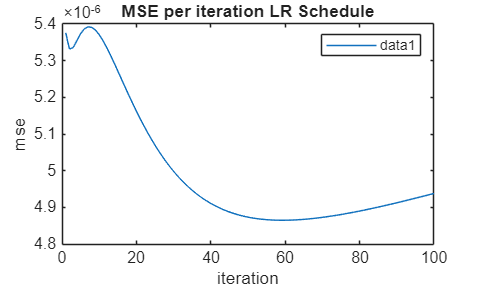

figure
plot(mse)
title('MSE per iteration LR Schedule')
xlabel('iteration')
ylabel('mse')
legend()

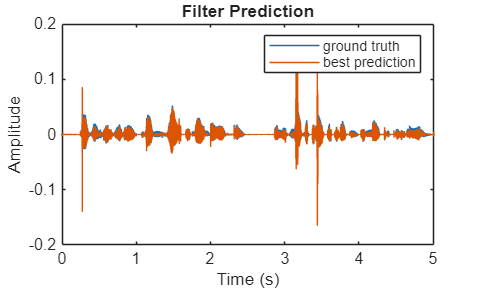

t = (0:length(target) - 1) / fs;
figure
plot(t, target)
hold on
plot(t, pred);
legend("ground truth", "best prediction")

title("Filter Prediction")
xlabel("Time (s)")
ylabel("Amplitude")
xlim([t(1), t(end)]);

hold off

figure
plot(fxlms.w)
xlabel('filter coeff')
ylabel('coeff value')
title('Learned Filter')
xlim([0, length(fxlms.w)])